## Concrete column with variable section area

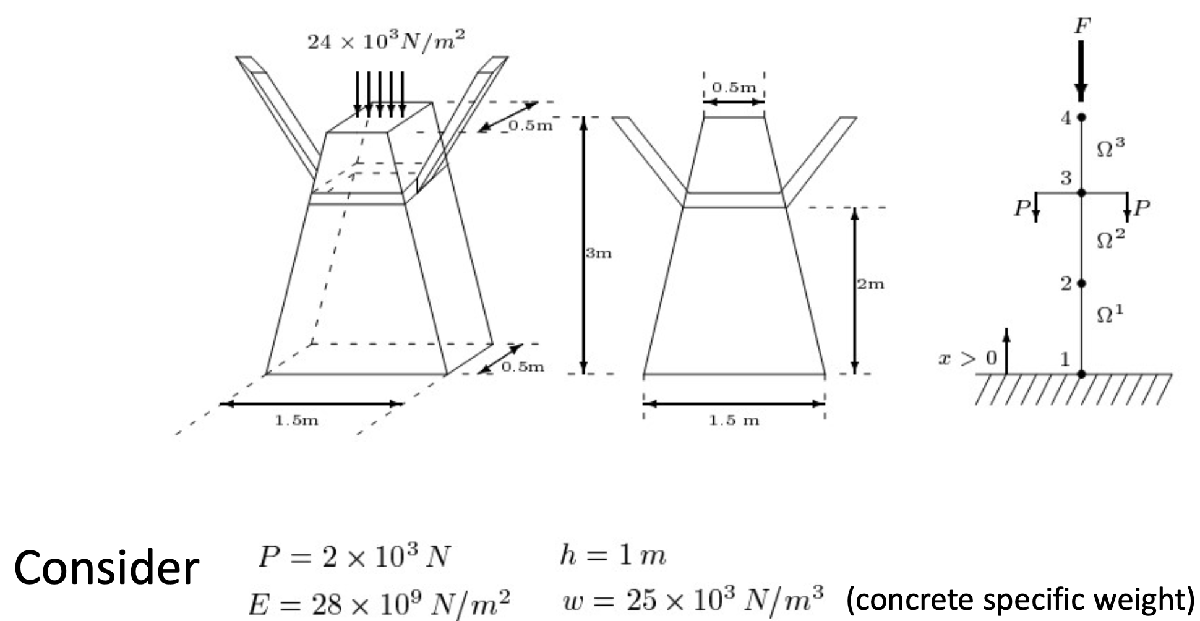

$\copyright$Numerical Factory

**Figure 1.** Dimensions of the piece, transverse section, loads, frontal plant, and meshing in 3 linear elements of lenght $h = 1\text{m}$ (image taken from professor Antonio Susin's Numerical Factory).

Notation


$$\begin{array}{l}
   L = 1.5 \text{m}  \text{(lenght of the bottom edge of the front section)},\\
   \ell = 0.5 \text{m}, \text{(length of the upper edge of the front section)},\\
  r = 0.5 \text{m}, \text{(width of the piece)}\\
  h = 1 \text{m (length of the three elements)},\\
  P = 2\times 10^{3} \text{N} \text{(loads at the third node)},\\
  E = 28\times 10^{9} \text{N/m}^{2} \text{(Young modulus)},\\
  F = 24\times 10^{3} \text{N/m}^{2} \text{(pressure at the top face)},\\
  w = 25\times 10^{3} \text{N/m}^{3} \text{(specific weight)}.

\end{array}$$


### Computation of local stifness matrices 

Comparing the coefficients in the 1D elasticity equation,


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(E A(x) \frac{\mathrm{d} u}{\mathrm{d} x}\right) = f(x),$$


with the 1D model equation,


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(a_{1}(x)\frac{\mathrm{d}u}{\mathrm{d} x}\right) + a_{0}(x) u = f(x),$$


and identifying coefficients, it is seen at once that $a_{0}(x) = 0$, and $a_{1}(x) = E A(x)$, where $A(x)$ is the area of  a transverse  section at height $x$ for $0 \le x\le 3$ which; after some elemental trigonometry, turns out to be an affine function of type $A(x) =\alpha x + \beta$, with $\alpha = -1/6$ and $\beta = 3/4$. On the other, hand, for linear elements,


$$\Omega^{e} = \left\{x\in\mathbb{R}; x^{e}_{1}\le x\le x^{e}_{2}\right\},$$


of length $h^{(e)} = x^{(e)}_{2} - x^{(e)}_{1}$, the shape functions and their corresponding derivatives are, respectively,


$$\psi^{(e)}_{k}(x) =(-1)^{k}\frac{x - x^{(e)}}{h^{(e)}}, \qquad\quad\frac{\mathrm{d}\psi^{(e)}}{\mathrm{d} x}(x) = \frac{(-1)^{k}}{h^{(e)}} ,$$


so computation of the integrals yield, for the compuments of the local stiffness matrix of element $\Omega^{e}$,


$$K^{(e),1}_{i,j} =(-1)^{i+j}\frac{E}{\left(h^{(e)}\right)^{2}}\int_{x^{(e)}_{1}}^{x^{(e)}_{2}} A(x)\mathrm{d} x = (-1)^{i+j}\frac{E}{\left(h^{(e)}\right)^{2}}\int_{x^{(e)}_{1}}^{x^{(e)}_{2}} \left(\beta + \alpha x\right)\mathrm{d} x = (-1)^{i+j} E\left(\frac{\beta}{h^{(e)}} + \frac{\alpha}{h^{(e)}}\left(\frac{x^{(e)}_{1} + x^{(e)}_{2}}{2}\right) \right),$$
 

for $i,j = 1,2$.

clearvars
close all

H =    3;             % m
nDiv = 3;             % m
P = 2.0e3;            % N
Force = 6.0e3;        % N

E = 28.0e9; %N/m^2
w = 25.0e3; %N/m^3

elem = [1:nDiv; 2:nDiv+1]' 

elem =      1     2
     2     3
     3     4



nodes = linspace(0,H,nDiv+1); nodes = nodes'

nodes =      0
     1
     2
     3



numElem = size(elem, 1);
numNodes = size(nodes, 1);

#### Càlcul de les K's

syms x x1 x2 alpha beta
psi = [(x-x2)/(x1-x2),(x-x1)/(x2-x1)]';
dpsi = diff(psi,x);
Ke = int((alpha+beta*x)*dpsi*dpsi',x,x1,x2)

$$Ke = \left(\begin{array}{cc} \frac{\beta }{2}-\frac{\alpha +\beta \,x_{1}}{x_{1}-x_{2}} & \frac{\beta }{2}+\frac{\alpha +\beta \,x_{2}}{x_{1}-x_{2}}\\ \frac{\beta }{2}+\frac{\alpha +\beta \,x_{2}}{x_{1}-x_{2}} & \frac{\beta }{2}-\frac{\alpha +\beta \,x_{1}}{x_{1}-x_{2}} \end{array}\right)$$

Veiem que $\alpha =3E/4$ i $\beta = -E/6$.

alpha = 3*E/4; beta = -E/6;
stiffnessMatrix = @(x1, x2) [alpha + 0.5*beta*(x1+x2)]*[1 -1; -1 1]/(x2-x1);

#### Càlcul de les F's

syms a b
Fe = int((a + b*x)*psi,x,x1,x2)

$$Fe = \left(\begin{array}{c} -\frac{\left(x_{1}-x_{2}\right)\,\left(3\,a+2\,b\,x_{1}+b\,x_{2}\right)}{6}\\ -\frac{\left(x_{1}-x_{2}\right)\,\left(3\,a+b\,x_{1}+2\,b\,x_{2}\right)}{6} \end{array}\right)$$

Veiem que $a = -3w/4$, $b=w/6$.

a = -w*3/4; b = w/6;
loadVector = @(x1,x2) (x2-x1)*(a*[1;1]/2 + b*[2*x1+x2; x1+2*x2]/6);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);
u = zeros(numNodes,1);


Acoplem les matrius 

for e = 1:numElem %Acoplem les matrius
    rows = [elem(e,1); elem(e,2)];
    cols = rows;
    x1 = nodes(rows(1)); x2 = nodes(rows(2)); 
    Ke = stiffnessMatrix(x1,x2)
    K(rows,cols) = K(rows,cols) + Ke
    Fe = loadVector(x1,x2)
    F(rows) = F(rows) + Fe
end

Ke = 1.0e+10 *

    1.8667   -1.8667
   -1.8667    1.8667


K = 1.0e+10 *

    1.8667   -1.8667         0         0
   -1.8667    1.8667         0         0
         0         0         0         0
         0         0         0         0


Fe = 1.0e+03 *

   -8.6806
   -7.9861


F = 1.0e+03 *

   -8.6806
   -7.9861
         0
         0


Ke = 1.0e+10 *

    1.4000   -1.4000
   -1.4000    1.4000


K = 1.0e+10 *

    1.8667   -1.8667         0         0
   -1.8667    3.2667   -1.4000         0
         0   -1.4000    1.4000         0
         0         0         0         0


Fe = 1.0e+03 *

   -6.5972
   -5.9028


F = 1.0e+04 *

   -0.8681
   -1.4583
   -0.5903
         0


Ke = 1.0e+09 *

    9.3333   -9.3333
   -9.3333    9.3333


K = 1.0e+10 *

    1.8667   -1.8667         0         0
   -1.8667    3.2667   -1.4000         0
         0   -1.4000    2.3333   -0.9333
         0         0   -0.9333    0.9333


Fe = 1.0e+03 *

   -4.5139
   -3.8194


F = 1.0e+04 *

   -0.8681
   -1.4583
   -1.0417
   -0.3819


Imposem les condicions de contorn

% Condicions de contorn
fixedNods = 1;
freeNods = setdiff(1:numNodes,fixedNods);

% Condicions de contorn naturals
Q(3) = -2*P

Q =            0
           0
       -4000
           0


Q(4) = -Force

Q =            0
           0
       -4000
       -6000


% Condicions de contorn essencials
u(1) = 0.0;

%Reduced system
Fm = Q(freeNods) + F(freeNods) - K(freeNods,fixedNods)*u(fixedNods)

Fm = 1.0e+04 *

   -1.4583
   -1.4417
   -0.9819


Km = K(freeNods,freeNods)

Km = 1.0e+10 *

    3.2667   -1.4000         0
   -1.4000    2.3333   -0.9333
         0   -0.9333    0.9333



%Solve the reduced system
um = Km\Fm;

u(freeNods) = um;

for i = 1:numNodes
    fprintf("u(%d) = %12.4 e mm\n",i,u(i)*1000)
end

u(1) = u(2) = u(3) = u(4) = 

Post process: find Q

Q = K*u - F;
for i = 1:numNodes
    fprintf("Q(%d) = %12.5e N\n",i,Q(i)*1000)
end

Q(1) =  4.75000e+07 N
Q(2) =  5.45697e-09 N
Q(3) = -4.00000e+06 N
Q(4) = -6.00000e+06 N
